Time = sltest_internal_rrSimulationOutputVariable.AxleTorque.Time;

axle_torque = sltest_internal_rrSimulationOutputVariable.AxleTorque.Data;
brake_deccel = sltest_internal_rrSimulationOutputVariable.BrakeDeccel.Data;
Dist_error = sltest_internal_rrSimulationOutputVariable.DistError.Data;
host_accel = sltest_internal_rrSimulationOutputVariable.HostAccel.Data;
host_jerk = sltest_internal_rrSimulationOutputVariable.HostJerk.Data;
host_velocity = sltest_internal_rrSimulationOutputVariable.HostVelocity.Data;
relative_veloctiy = sltest_internal_rrSimulationOutputVariable.relativeVel.Data;



% figure;
% For plotting the run with weights qvh = 0, qah = 5, qdistError = 100, qvrel = 50, rTaxle = 1, rabrake = 1 
% subplot(4,1,1); % 4 rows, 1 column, top plot
% plot(Time, host_velocity, 'b-', 'LineWidth', 1.5); hold on;
% title('Host Velocity');
% xlabel('Time (s)');
% ylabel('m/s');
% % legend('Velocity');
% grid on;
% 
% subplot(4,1,2); % 4 rows, 1 column, third plot
% plot(Time, axle_torque, 'b-', 'LineWidth', 1.5); hold on;
% title('Axle Torque Command');
% xlabel('Time (s)');
% ylabel('Nm');
% % legend('Relative Velocity');
% grid on;
% 
% subplot(4,1,3); % 4 rows, 1 column, second plot
% plot(Time, relative_veloctiy, 'b-', 'LineWidth', 1.5); hold on;
% title('Relative Velocity');
% xlabel('Time (s)');
% ylabel('m/s');
% % legend('Relative Velocity');
% grid on;
% 
% subplot(4,1,4); % 4 rows, 1 column, third plot
% plot(Time, Dist_error, 'b-', 'LineWidth', 1.5); hold on;
% title('Following Distance Error');
% xlabel('Time (s)');
% ylabel('m');
% % legend('Relative Velocity');
% grid on;
 

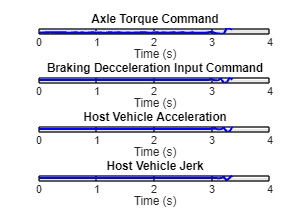

% For plotting the run with weights  qvh = 0, qah = 20, qdistError = 100, qvrel = 50, rTaxle = 0.0005, rabrake = 0.1
figure;
%% set of plots for the inputs and acceleration and jerk states
subplot(4,1,1);
plot(Time, axle_torque, 'b-', 'LineWidth', 1.5); hold on;
title('Axle Torque Command');
xlabel('Time (s)');
ylabel('Nm');
grid on;

subplot(4,1,2);
plot(Time, brake_deccel, 'b-', 'LineWidth', 1.5); hold on;
title('Braking Decceleration Input Command');
xlabel('Time (s)');
ylabel('m/s^2');
grid on;

subplot(4,1,3);
plot(Time, host_accel, 'b-', 'LineWidth', 1.5); hold on;
title('Host Vehicle Acceleration');
xlabel('Time (s)');
ylabel('m/s^2');
grid on;

subplot(4,1,4);
plot(Time, host_jerk, 'b-', 'LineWidth', 1.5); hold on;
title('Host Vehicle Jerk');
xlabel('Time (s)');
ylabel('m/s^3');
grid on;

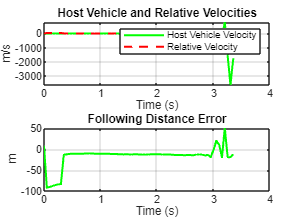


figure;
%% This is for the velocity and error states
subplot (2,1,1);
plot(Time, host_velocity,'g-','LineWidth', 1.5); hold on;
plot(Time,relative_veloctiy, 'r--', 'LineWidth', 1.5);
title('Host Vehicle and Relative Velocities');
xlabel('Time (s)');
ylabel('m/s');
legend('Host Vehicle Velocity', 'Relative Velocity');
grid on;

subplot (2,1,2);
plot(Time, Dist_error,'g-','LineWidth', 1.5); hold on;
title('Following Distance Error');
xlabel('Time (s)');
ylabel('m');
grid on;

% For plotting the unaugmented system with the jerk constraints; Jmax = 8; qvh = 0, qah = 20, qdistError = 100, qvrel = 50, rTaxle = 0.0005, rabrake = 0.1
